# KEVIN JAUKI

%% Environmental Brain Cube - Modes Analysis
% This script checks how close one mode run was to a chosen condition.
%
% It does these things:
% - reads the modes log file
% - picks one run
% - compares run averages to all conditions
% - makes plots
% - shows simple tables and conclusions
% - makes final match of environment profile
%

clear; clc; close all;

%% settings
fileName = "ebc_modes_log.csv";   
runChoice = "15";            % "latest" or a run number like "2" (make sure run number is accurate and quoted"")

%% condition table
% should match Arduino code
profiles = table( ...
    ["NORMAL"; "WARM_HUMID"; "WARM_DRY"; "COLD"], ...
    [20.0; 26.0; 24.0; 4.0], ...
    [24.0; 32.0; 30.0; 12.0], ...
    [30.0; 60.0; 15.0; 35.0], ...
    [50.0; 70.0; 35.0; 65.0], ...
    [995.0; 995.0; 995.0; 995.0], ...
    [1025.0; 1025.0; 1025.0; 1025.0], ...
    'VariableNames', {'Name','TempMin','TempMax','HumMin','HumMax','PresMin','PresMax'});

%% check file
if ~isfile(fileName)
    error("File not found: " + fileName);
end

%% read file lines
txt = fileread(fileName);
lines = splitlines(string(txt));
lines = strtrim(lines);
lines = lines(lines ~= "");

%% keep only real RUN rows
dataLines = strings(0,1);

for i = 1:length(lines)
    lineNow = lines(i);

    if startsWith(lineNow, "RUN") && ~startsWith(lineNow, "=== RUN")
        parts = split(lineNow, ",");
        if numel(parts) >= 30
            dataLines(end+1,1) = lineNow; %#ok<SAGROW>
        end
    end
end

if isempty(dataLines)
    error("No valid RUN data rows found.");
end

%% make arrays
n = length(dataLines);

runNum = nan(n,1);
timeSec = nan(n,1);

lightMin = nan(n,1);
lightMax = nan(n,1);
lightState = strings(n,1);

bmeTempMin = nan(n,1);
bmeTempMax = nan(n,1);

bmeHumMin = nan(n,1);
bmeHumMax = nan(n,1);

bmePresMin = nan(n,1);
bmePresMax = nan(n,1);

dsTempMin = nan(n,1);
dsTempMax = nan(n,1);

battMin = nan(n,1);
battMax = nan(n,1);

solarMin = nan(n,1);
solarMax = nan(n,1);

axMin = nan(n,1);
axMax = nan(n,1);

ayMin = nan(n,1);
ayMax = nan(n,1);

azMin = nan(n,1);
azMax = nan(n,1);

gxMin = nan(n,1);
gxMax = nan(n,1);

gyMin = nan(n,1);
gyMax = nan(n,1);

gzMin = nan(n,1);
gzMax = nan(n,1);

%% pull values from each row
for i = 1:n
    row = split(dataLines(i), ",");
    row = strtrim(row);

    runNum(i) = sscanf(row(1), "RUN%d");
    timeSec(i) = makeNum(row(3));

    lightMin(i) = makeNum(row(4));
    lightMax(i) = makeNum(row(5));
    lightState(i) = row(6);

    bmeTempMin(i) = makeNum(row(7));
    bmeTempMax(i) = makeNum(row(8));

    bmeHumMin(i) = makeNum(row(9));
    bmeHumMax(i) = makeNum(row(10));

    bmePresMin(i) = makeNum(row(11));
    bmePresMax(i) = makeNum(row(12));

    dsTempMin(i) = makeNum(row(13));
    dsTempMax(i) = makeNum(row(14));

    battMin(i) = makeNum(row(15));
    battMax(i) = makeNum(row(16));

    solarMin(i) = makeNum(row(17));
    solarMax(i) = makeNum(row(18));

    axMin(i) = makeNum(row(19));
    axMax(i) = makeNum(row(20));

    ayMin(i) = makeNum(row(21));
    ayMax(i) = makeNum(row(22));

    azMin(i) = makeNum(row(23));
    azMax(i) = makeNum(row(24));

    gxMin(i) = makeNum(row(25));
    gxMax(i) = makeNum(row(26));

    gyMin(i) = makeNum(row(27));
    gyMax(i) = makeNum(row(28));

    gzMin(i) = makeNum(row(29));
    gzMax(i) = makeNum(row(30));
end

%% make table
T = table(runNum,timeSec,...
    lightMin,lightMax,lightState,...
    bmeTempMin,bmeTempMax,...
    bmeHumMin,bmeHumMax,...
    bmePresMin,bmePresMax,...
    dsTempMin,dsTempMax,...
    battMin,battMax,...
    solarMin,solarMax,...
    axMin,axMax,...
    ayMin,ayMax,...
    azMin,azMax,...
    gxMin,gxMax,...
    gyMin,gyMax,...
    gzMin,gzMax);

%% choose run
allRuns = unique(T.runNum);

if runChoice == "latest"
    runToUse = max(allRuns);
else
    runToUse = double(runChoice);
end

D = T(T.runNum == runToUse, :);
D = sortrows(D, "timeSec");

if isempty(D)
    error("Selected run not found.");
end

fprintf("Using RUN%d\n", runToUse);

Using RUN15


fprintf("Intervals logged: %d\n", height(D));

Intervals logged: 149


fprintf("Run duration: %.2f s\n", max(D.timeSec));

Run duration: 300.03 s



%% midpoint values
D.bmeTempMid = (D.bmeTempMin + D.bmeTempMax) / 2;
D.dsTempMid  = (D.dsTempMin  + D.dsTempMax) / 2;
D.bmeHumMid  = (D.bmeHumMin  + D.bmeHumMax) / 2;
D.bmePresMid = (D.bmePresMin + D.bmePresMax) / 2;

%% average values for fit
avgBmeTemp = mean(D.bmeTempMid, 'omitnan');
avgDsTemp  = mean(D.dsTempMid, 'omitnan');
avgHum     = mean(D.bmeHumMid, 'omitnan');
avgPres    = mean(D.bmePresMid, 'omitnan');

% use BME air temp for matching condition
avgTempForFit = avgBmeTemp;

%% compare to all conditions and rank them
envName = strings(height(profiles),1);

tempPassAll = false(height(profiles),1);
humPassAll = false(height(profiles),1);
presPassAll = false(height(profiles),1);

tempCloseAll = nan(height(profiles),1);
humCloseAll = nan(height(profiles),1);
presCloseAll = nan(height(profiles),1);

tempOffsetAll = nan(height(profiles),1);
humOffsetAll = nan(height(profiles),1);
presOffsetAll = nan(height(profiles),1);

matchCountAll = nan(height(profiles),1);
overallClosenessAll = nan(height(profiles),1);

for k = 1:height(profiles)
    envName(k) = profiles.Name(k);

    [tempPassAll(k), tempCloseAll(k), tempOffsetAll(k)] = compareToRange(avgTempForFit, profiles.TempMin(k), profiles.TempMax(k));
    [humPassAll(k), humCloseAll(k), humOffsetAll(k)] = compareToRange(avgHum, profiles.HumMin(k), profiles.HumMax(k));
    [presPassAll(k), presCloseAll(k), presOffsetAll(k)] = compareToRange(avgPres, profiles.PresMin(k), profiles.PresMax(k));

    matchCountAll(k) = sum([tempPassAll(k), humPassAll(k), presPassAll(k)]);
    overallClosenessAll(k) = mean([tempCloseAll(k), humCloseAll(k), presCloseAll(k)], 'omitnan');
end

%% ranked environment table
EnvironmentRanking = table( ...
    envName, ...
    matchCountAll, ...
    overallClosenessAll, ...
    tempPassAll, humPassAll, presPassAll, ...
    tempCloseAll, humCloseAll, presCloseAll, ...
    tempOffsetAll, humOffsetAll, presOffsetAll, ...
    'VariableNames', ...
    {'Environment','MatchCount','OverallClosenessPercent', ...
     'TempPass','HumPass','PresPass', ...
     'TempClosenessPercent','HumClosenessPercent','PresClosenessPercent', ...
     'TempCenterOffsetPercent','HumCenterOffsetPercent','PresCenterOffsetPercent'});

EnvironmentRanking = sortrows(EnvironmentRanking, {'MatchCount','OverallClosenessPercent'}, {'descend','descend'});

EnvironmentRanking

EnvironmentRanking = 4×12 table
    Environment     MatchCount    OverallClosenessPercent    TempPass    HumPass    PresPass    TempClosenessPercent    HumClosenessPercent    PresClosenessPercent    TempCenterOffsetPercent    HumCenterOffsetPercent    PresCenterOffsetPercent
    ____________    __________    _______________________    ________    _______    ________    ____________________    ___________________    ____________________    _______________________    ______________________    _______________________

    "WARM_HUMID"        2                 49.947              true     


%% choose best condition automatically
selectedCondition = EnvironmentRanking.Environment(1);
profileRow = profiles(profiles.Name == selectedCondition, :);

disp("Best matched condition:")

Best matched condition:


disp(profileRow)

        Name        TempMin    TempMax    HumMin    HumMax    PresMin    PresMax
    ____________    _______    _______    ______    ______    _______    _______

    "WARM_HUMID"      26         32         60        70        995       1025  




%% compare to selected condition
[tempPass, tempClose, tempOffset] = compareToRange(avgTempForFit, profileRow.TempMin, profileRow.TempMax);
[humPass, humClose, humOffset] = compareToRange(avgHum, profileRow.HumMin, profileRow.HumMax);
[presPass, presClose, presOffset] = compareToRange(avgPres, profileRow.PresMin, profileRow.PresMax);

overallCloseness = mean([tempClose, humClose, presClose], 'omitnan');
matchCount = sum([tempPass, humPass, presPass]);

%% comparison table
Parameter = ["Temperature"; "Humidity"; "Pressure"];
RunAverage = [avgTempForFit; avgHum; avgPres];
TargetMin = [profileRow.TempMin; profileRow.HumMin; profileRow.PresMin];
TargetMax = [profileRow.TempMax; profileRow.HumMax; profileRow.PresMax];
Pass = [tempPass; humPass; presPass];
ClosenessPercent = [tempClose; humClose; presClose];
CenterOffsetPercent = [tempOffset; humOffset; presOffset];

ComparisonTable = table(Parameter, RunAverage, TargetMin, TargetMax, ...
    Pass, ClosenessPercent, CenterOffsetPercent);

ComparisonTable

ComparisonTable = 3×7 table
      Parameter      RunAverage    TargetMin    TargetMax    Pass     ClosenessPercent    CenterOffsetPercent
    _____________    __________    _________    _________    _____    ________________    ___________________

    "Temperature"      30.061          26           32       true          64.621               35.379       
    "Humidity"         75.585          60           70       false              0               211.69       
    "Pressure"         1007.8         995         1025       true          85.221               14.779       



%% overall summary table
OverallSummary = table( ...
    string(selectedCondition), ...
    runToUse, ...
    max(D.timeSec), ...
    avgBmeTemp, ...
    avgDsTemp, ...
    avgHum, ...
    avgPres, ...
    matchCount, ...
    overallCloseness, ...
    'VariableNames', ...
    {'Condition','Run','DurationSec','AvgBmeTemp','AvgDsTemp','AvgHumidity','AvgPressure','MatchCount','OverallClosenessPercent'});

OverallSummary

OverallSummary = 1×9 table
     Condition      Run    DurationSec    AvgBmeTemp    AvgDsTemp    AvgHumidity    AvgPressure    MatchCount    OverallClosenessPercent
    ____________    ___    ___________    __________    _________    ___________    ___________    __________    _______________________

    "WARM_HUMID"    15       300.03         30.061       21.247        75.585         1007.8           2                 49.947         


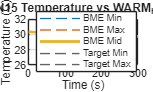


%% temperature plot
figure
plot(D.timeSec, D.bmeTempMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.bmeTempMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.bmeTempMid, 'LineWidth', 2)
yline(profileRow.TempMin, '--', 'Target Min')
yline(profileRow.TempMax, '--', 'Target Max')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')
title("RUN" + runToUse + " Temperature vs " + selectedCondition)
legend('BME Min','BME Max','BME Mid','Target Min','Target Max','Location','best')

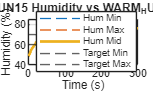


%% humidity plot
figure
plot(D.timeSec, D.bmeHumMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.bmeHumMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.bmeHumMid, 'LineWidth', 2)
yline(profileRow.HumMin, '--', 'Target Min')
yline(profileRow.HumMax, '--', 'Target Max')
grid on
xlabel('Time (s)')
ylabel('Humidity (%)')
title("RUN" + runToUse + " Humidity vs " + selectedCondition)
legend('Hum Min','Hum Max','Hum Mid','Target Min','Target Max','Location','best')

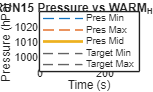


%% pressure plot
figure
plot(D.timeSec, D.bmePresMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.bmePresMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.bmePresMid, 'LineWidth', 2)
yline(profileRow.PresMin, '--', 'Target Min')
yline(profileRow.PresMax, '--', 'Target Max')
grid on
xlabel('Time (s)')
ylabel('Pressure (hPa)')
title("RUN" + runToUse + " Pressure vs " + selectedCondition)
legend('Pres Min','Pres Max','Pres Mid','Target Min','Target Max','Location','best')

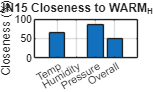


%% closeness bar chart
figure
bar([tempClose, humClose, presClose, overallCloseness])
set(gca, 'XTickLabel', {'Temp','Humidity','Pressure','Overall'})
ylabel('Closeness (%)')
title("RUN" + runToUse + " Closeness to " + selectedCondition)
grid on


%% simple conclusions
fprintf('\n================ CONDITION COMPARISON ================\n');


================ CONDITION COMPARISON ================


fprintf('Run analyzed: RUN%d\n', runToUse);

Run analyzed: RUN15


fprintf('Best matched condition: %s\n', selectedCondition);

Best matched condition: WARM_HUMID


fprintf('Run duration: %.2f s\n', max(D.timeSec));

Run duration: 300.03 s



fprintf('\nAverage run values used for comparison:\n');


Average run values used for comparison:


fprintf('- BME temperature average: %.2f C\n', avgBmeTemp);

- BME temperature average: 30.06 C


fprintf('- DS temperature average: %.2f C\n', avgDsTemp);

- DS temperature average: 21.25 C


fprintf('- Humidity average: %.2f %%\n', avgHum);

- Humidity average: 75.58 %


fprintf('- Pressure average: %.2f hPa\n', avgPres);

- Pressure average: 1007.78 hPa



fprintf('\nBest matched condition ranges:\n');


Best matched condition ranges:


fprintf('- Temperature: %.1f to %.1f C\n', profileRow.TempMin, profileRow.TempMax);

- Temperature: 26.0 to 32.0 C


fprintf('- Humidity: %.1f to %.1f %%\n', profileRow.HumMin, profileRow.HumMax);

- Humidity: 60.0 to 70.0 %


fprintf('- Pressure: %.1f to %.1f hPa\n', profileRow.PresMin, profileRow.PresMax);

- Pressure: 995.0 to 1025.0 hPa



fprintf('\nParameter results:\n');


Parameter results:


fprintf('- Temperature: %s | closeness %.1f %%\n', passText(tempPass), tempClose);

- Temperature: PASS | closeness 64.6 %


fprintf('- Humidity: %s | closeness %.1f %%\n', passText(humPass), humClose);

- Humidity: FAIL | closeness 0.0 %


fprintf('- Pressure: %s | closeness %.1f %%\n', passText(presPass), presClose);

- Pressure: PASS | closeness 85.2 %



fprintf('\nOverall:\n');


Overall:


fprintf('- Match count: %d/3\n', matchCount);

- Match count: 2/3


fprintf('- Overall closeness: %.1f %%\n', overallCloseness);

- Overall closeness: 49.9 %



if matchCount == 3
    fprintf('- The run fits the matched condition well overall.\n');
elseif matchCount == 2
    fprintf('- The run is fairly close, but one value is outside range.\n');
elseif matchCount == 1
    fprintf('- The run only weakly matches the matched condition.\n');
else
    fprintf('- The run does not closely match the matched condition.\n');
end

- The run is fairly close, but one value is outside range.



fprintf('\nEnvironment ranking from best to worst:\n');


Environment ranking from best to worst:


for i = 1:height(EnvironmentRanking)
    fprintf('%d. %s | match %d/3 | closeness %.1f %%\n', ...
        i, EnvironmentRanking.Environment(i), ...
        EnvironmentRanking.MatchCount(i), ...
        EnvironmentRanking.OverallClosenessPercent(i));
end

1. WARM_HUMID | match 2/3 | closeness 49.9 %
2. NORMAL | match 1/3 | closeness 28.4 %
3. WARM_DRY | match 1/3 | closeness 28.4 %
4. COLD | match 1/3 | closeness 28.4 %



fprintf('======================================================\n');



function x = makeNum(s)
    s = strtrim(string(s));

    if s == "NA" || s == ""
        x = NaN;
    else
        x = str2double(s);
    end
end

function [isPass, closeness, centerOffsetPercent] = compareToRange(v, vMin, vMax)
    if isnan(v)
        isPass = false;
        closeness = NaN;
        centerOffsetPercent = NaN;
        return
    end

    center = (vMin + vMax) / 2;
    halfRange = (vMax - vMin) / 2;

    if halfRange <= 0
        isPass = false;
        closeness = NaN;
        centerOffsetPercent = NaN;
        return
    end

    centerOffsetPercent = abs(v - center) / halfRange * 100;
    closeness = max(0, 100 - centerOffsetPercent);
    isPass = (v >= vMin) && (v <= vMax);
end

function txt = passText(tf)
    if tf
        txt = 'PASS';
    else
        txt = 'FAIL';
    end
end